This section assumes that you have access to the functions and basic kinematics of 4-CLARI. If you do not have access to the file "Data\nonslip4CLARIMobility.mat" from the root folder, then run the first section (might take some time to complete, maybe time it if needed) in "se2_fixedCLARImobility.mlx".

addpath(genpath('Data')); addpath(genpath('Utility Functions'));
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
load('Data\nonslip4CLARIMobility.mat');

Generate a qualitative colormap to plot different trajectories. Insert the desired colormap and run the code below to affect the plots generated in the rest of the document.

qualColMap = [31,120,180;
                178,223,138;
                51,160,44;
                251,154,153;
                227,26,28;
                253,191,111;
                255,127,0;
                202,178,214;
                106,61,154]/255;
qualColMap = resizeColorMap( qualColMap, size(turbo, 1) );
save('Data\Plotting\qualitativeColorMap.mat', "qualColMap");

Generate a diverging colormap used to display constraint curvature functions (CCF) and stratified panels ($dz$) from previous work.

% this colormap is originally defined in: "se2_toyproblems_case_1.mlx"
divColMap = flipud([159.3750,99.6030,63.4312;
                    239.0625,149.4045,95.1469;
                    255.0000,199.2060,126.8625;
                    204.0000,204.0000,204.0000;
                    150.0000,150.0000,150.0000;
                    99.0000,  99.0000, 99.0000])/255;
divColMap = resizeColorMap( divColMap, size(turbo, 1) );
save('Data\Plotting\divergingColorMap.mat', "divColMap");

Before we even consider the gait design and maneuverability aspects, we first consider the local connection vector fields in each contact state for a trot gait and save the data for plotting.

% some parameters setup - plotting and other s ystem construction
sIdx = cs_IdxFor2bGaits(strcmp(csString, 'Trot'), :); % obtain the current contact submanifolds for 
na = limbScalingParam(end); nl = 1; % clari system construction params
% nalpha_b = bodySprawlParam(end); % just set the omnidirectional (nominal) body sprawl angle
dNumQ = floor(0.1*dnum)-1; % number of quivers to plot in each dirn
nalphaVec = linspace(limbAngleParam(1), limbAngleParam(2), dNumQ); % create a vector of limb angles
[nalpha_x, nalpha_y] = meshgrid(nalphaVec, nalphaVec); % obtain the 2D grid of limb angles
angleLimits = rad2deg(...
    [limbAngleParam(1), limbAngleParam(2)] ... % actual range
    + 0.07*diff(limbAngleParam(1:2), 1)*[-1, 1]... % 7% padding
                        );
angleTicks  = round(  ...
                 rad2deg( ...
                     linspace(limbAngleParam(1), limbAngleParam(2), 5) ...
                         )  ...
                     );
col13 = col(5, :); col24 = col(6, :);

% sweep the body sprawl angles
sNum = 7; % CHOOSE a small number of angles to sweep the set over
nalpha_b = linspace(bodySprawlParam(1), bodySprawlParam(2), sNum);

% a function to compute the nominal bodylength of the robot for normalization
nominalBodyLength = matlabFunction( ...
            simplify(norm(boxCornersFromBody(2, 1:2) - boxCornersFromBody(4, 1:2))), ...
            "Vars", [l, alpha_b] ...
                                    );

% extract the local connections in each stance subspace
% ... this will be each column of A_i or fA_i
% ... u and v denote the directions of the quiver along each limb fore-aft
% ... angle direction in the current contact state
fAu = {  fA_i_col1{ sIdx(1) }; fA_i_col1{ sIdx(2) }  };
fAv = {  fA_i_col2{ sIdx(1) }; fA_i_col2{ sIdx(2) }  };

% obtain the local connection values for each direction
temp = cell(1, sNum);
nAu_13_sweep = temp; nAu_13_X = temp; nAu_13_Y = temp; nAu_13_TH = temp;
nAv_13_sweep = temp; nAv_13_X = temp; nAv_13_Y = temp; nAv_13_TH = temp;
nAu_24_sweep = temp; nAu_24_X = temp; nAu_24_Y = temp; nAu_24_TH = temp;
nAv_24_sweep = temp; nAv_24_X = temp; nAv_24_Y = temp; nAv_24_TH = temp;
for i = 1:sNum
    nAu_13_sweep{i} = -fAu{1}(na, nl, nalpha_b(i), nalpha_x(:)', nalpha_y(:)'); % components in 13 stance
    nAu_13_X{i}  = reshape( nAu_13_sweep{i}(1, :), [dNumQ, dNumQ] );
    nAu_13_Y{i}  = reshape( nAu_13_sweep{i}(2, :), [dNumQ, dNumQ] );
    nAu_13_TH{i} = reshape( nAu_13_sweep{i}(3, :), [dNumQ, dNumQ] );
    nAv_13_sweep{i} = -fAv{1}(na, nl, nalpha_b(i), nalpha_x(:)', nalpha_y(:)');
    nAv_13_X{i}  = reshape( nAv_13_sweep{i}(1, :), [dNumQ, dNumQ] );
    nAv_13_Y{i}  = reshape( nAv_13_sweep{i}(2, :), [dNumQ, dNumQ]);
    nAv_13_TH{i} = reshape( nAv_13_sweep{i}(3, :), [dNumQ, dNumQ] );
    nAu_24_sweep{i} = -fAu{2}(na, nl, nalpha_b(i), nalpha_x(:)', nalpha_y(:)'); % components in 24 stance
    nAu_24_X{i}  = reshape( nAu_24_sweep{i}(1, :), [dNumQ, dNumQ] );
    nAu_24_Y{i}  = reshape( nAu_24_sweep{i}(2, :), [dNumQ, dNumQ] );
    nAu_24_TH{i} = reshape( nAu_24_sweep{i}(3, :), [dNumQ, dNumQ] );
    nAv_24_sweep{i} = -fAv{2}(na, nl, nalpha_b(i), nalpha_x(:)', nalpha_y(:)');
    nAv_24_X{i}  = reshape( nAv_24_sweep{i}(1, :), [dNumQ, dNumQ] );
    nAv_24_Y{i}  = reshape( nAv_24_sweep{i}(2, :), [dNumQ, dNumQ] );
    nAv_24_TH{i} = reshape( nAv_24_sweep{i}(3, :), [dNumQ, dNumQ] );
end

% save the connection vector field sweep data
save('Data\Sinusoidal Gaits\clariConnVecF', ...
    "sIdx", ...
    "na", "nl", "nalpha_b", ...
    "nominalBodyLength", ...
    "dnum", "dNumQ", ...
    "nalpha_x", "nalpha_y", ...
    "angleLimits", "angleTicks", ...
    "col13", "col24", "lW_Vector", "lW_V", "lW_s", "lW_c", ...
    "fAu", "fAv", ...
    "sNum", ...
    "nAu_13_sweep", "nAu_13_X", "nAu_13_Y", "nAu_13_TH", ...
    "nAv_13_sweep", "nAv_13_X", "nAv_13_Y", "nAv_13_TH", ...
    "nAu_24_sweep", "nAu_24_X", "nAu_24_Y", "nAu_24_TH", ...
    "nAv_24_sweep", "nAv_24_X", "nAv_24_Y", "nAv_24_TH", '-mat');

addpath(genpath('Data')); addpath(genpath('Utility Functions'));
load('Data\Sinusoidal Gaits\clariConnVecF.mat');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex'); 
set(groot, 'defaulttextinterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');

Let's now plot the connection vector fields for a trot gait in CLARI's omnidirectional configuration.

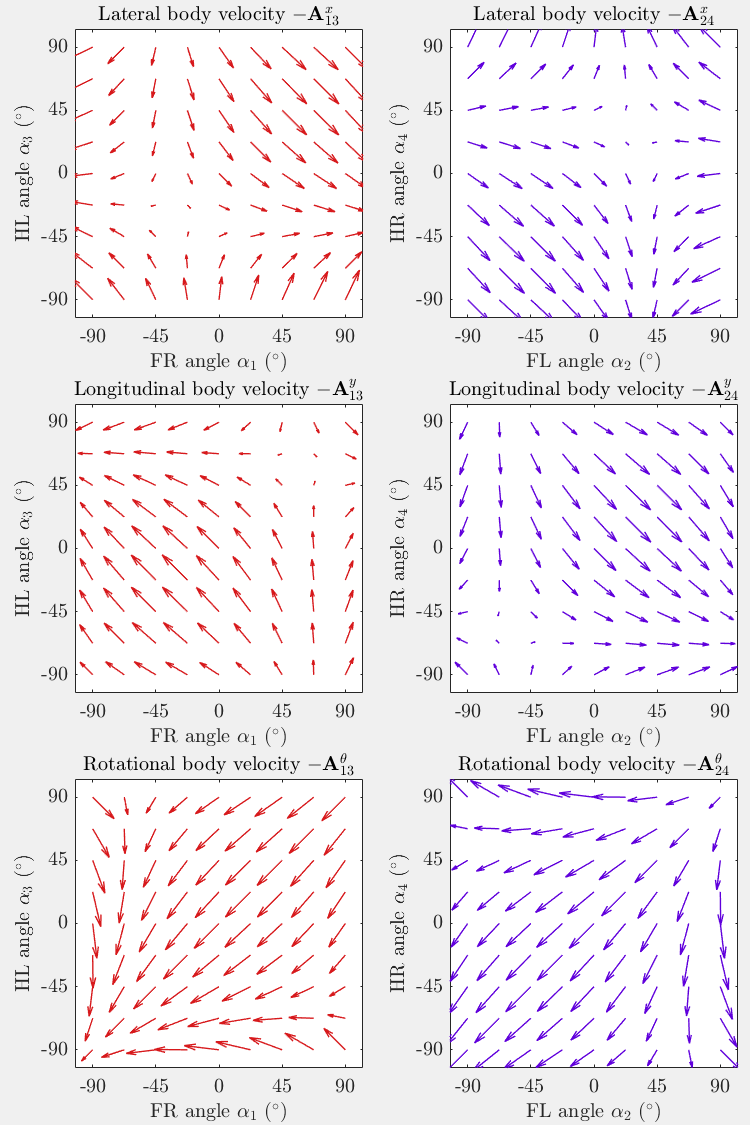

plotTrotLocalConnWOGaits( floor(sNum/2) ); 

% Omnidirectional sprawl should tbe the middle index of the sprawl angle
% sweep from the previous section. It is important to ensure that the sweep
% discretization is an odd number.

addpath(genpath('Data')); addpath(genpath('Utility Functions'));
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
load('Data\nonslip4CLARIMobility.mat');

load('Data\Sinusoidal Gaits\clariConnVecF.mat');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex'); 
set(groot, 'defaulttextinterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');

It's elementary to construct longitudinal/lateral gaits for the omnidirectional sprawl configuration of the clari robot based on a mobile robot analogy with wheels instead of legs. The longitudinal and lateral gaits are shown below:

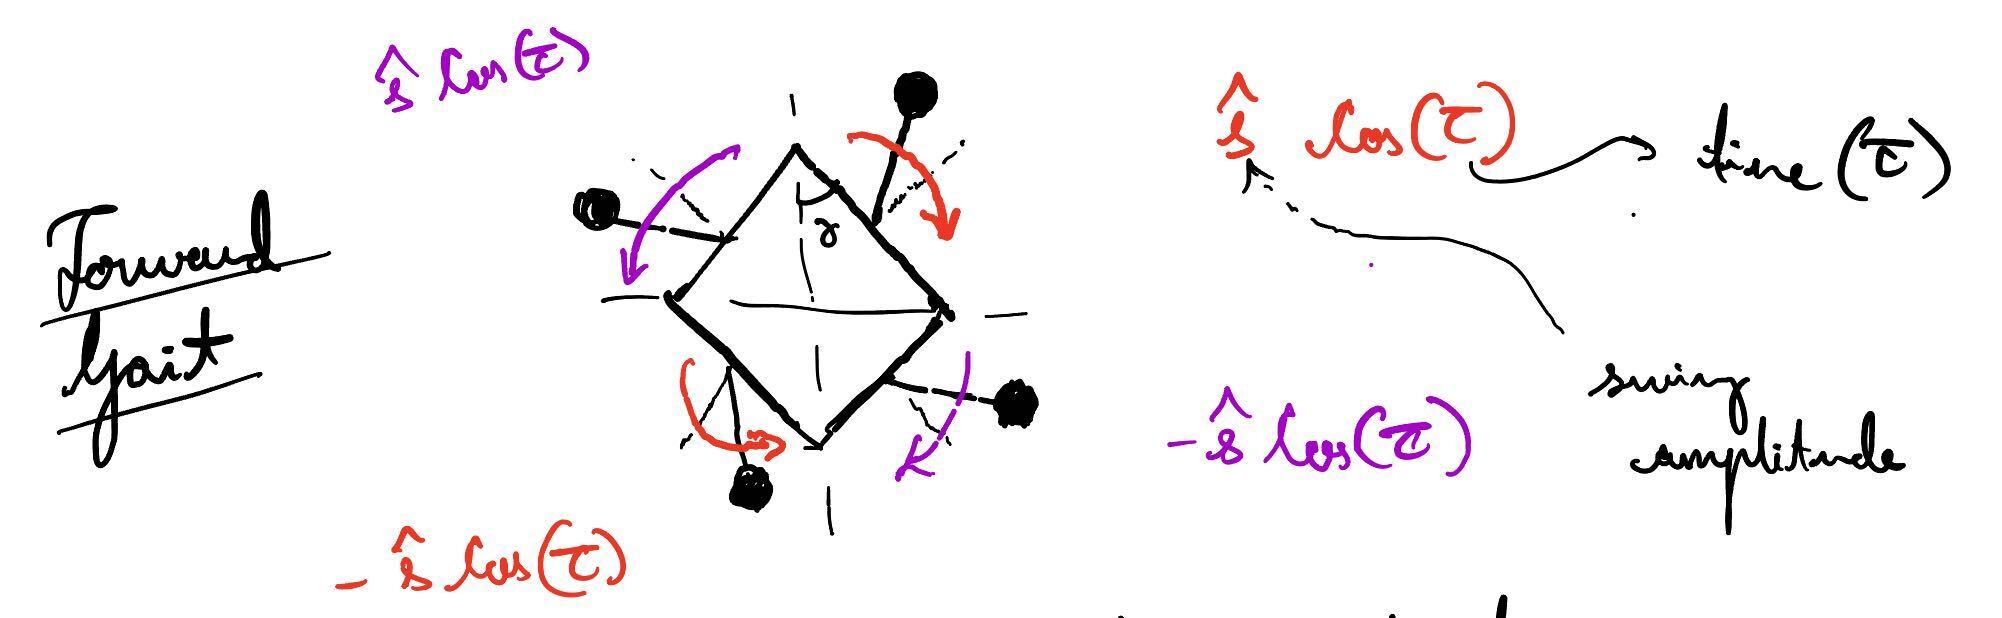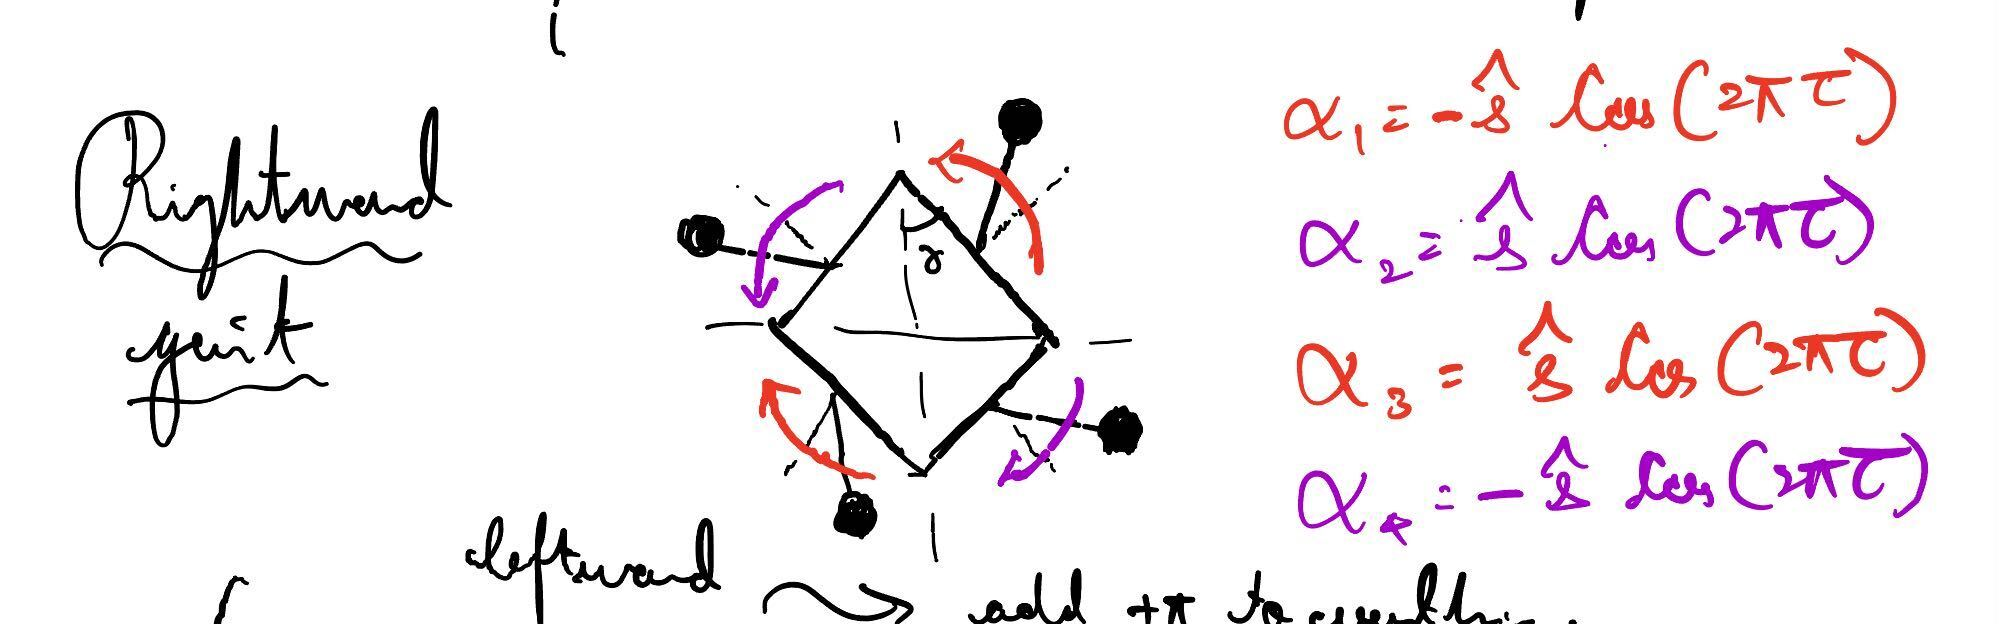

As an example we assume the limb fore-aft amplitude for these trajectories is $45^{\circ}$.

To get a sense for how these gaits generate displacement, we plot the stance phase trajectories onto the connection vector fields.

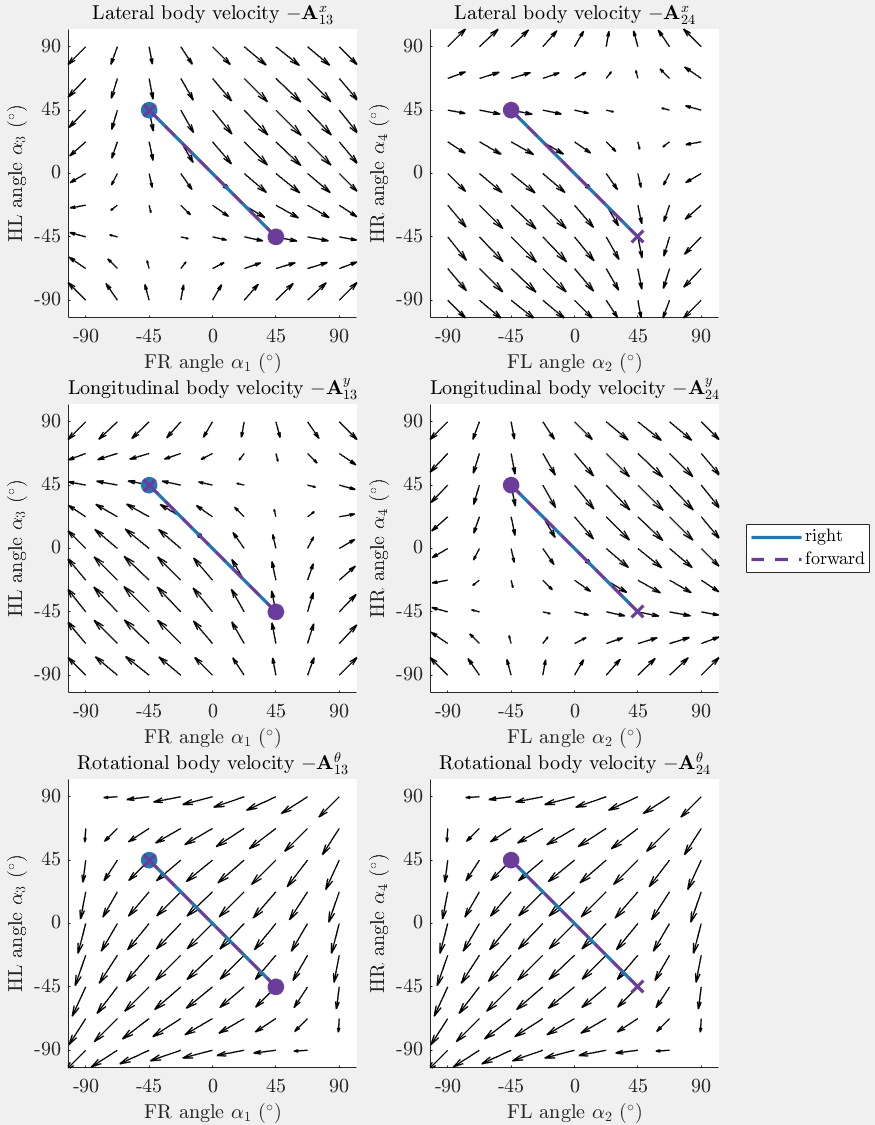

% initial params for simulation
sHat = pi/4; % limb fore-aft amplitude in rad
t = linspace(0, 1, dnum); % gait time vector

% construct the stance trajectories for the considered gaits
% ... 1) using prewritten functions we first compute the phasing between the
% ...    sinusoids for each leg
% ...        displacement phasor = 0     => right gait    - 0
% ...        displacement phasor = pi/2  => forward gait  - 0.25
% ... 2) then we compute the trajectories for all the legs and plot the
% ...    corresponding stance phases on each vector field
sPhase_Rht = computeSineShapePhaseV1( 0.0 );
[phiRht, ~] = computeSineShapeTrajectoriesV1(t, sHat, sPhase_Rht);
phiRhtWt = [t(:)'; phiRht];
sPhase_Fwd = computeSineShapePhaseV1( 0.25 );
[phiFwd, ~] = computeSineShapeTrajectoriesV1(t, sHat, sPhase_Fwd);
phiFwdWt = [t(:)'; phiFwd];

% choose the omnidirectional configuration
bsIdx = ceil(sNum/2);

% plot the trajectories
plotTrotLocalConnWGaits( ...
    bsIdx, ... % choose the omnidirectional configuration
    {phiRhtWt, phiFwdWt}, ... % provide gaits
    {'right', 'forward'}, ... % provide labels for the gaits to generate a legend
    true ); % just use black trace for vector field, else saturate to white (feels "washed-out")

Similarly, compute and plot the displacement generated by these gait cycles.

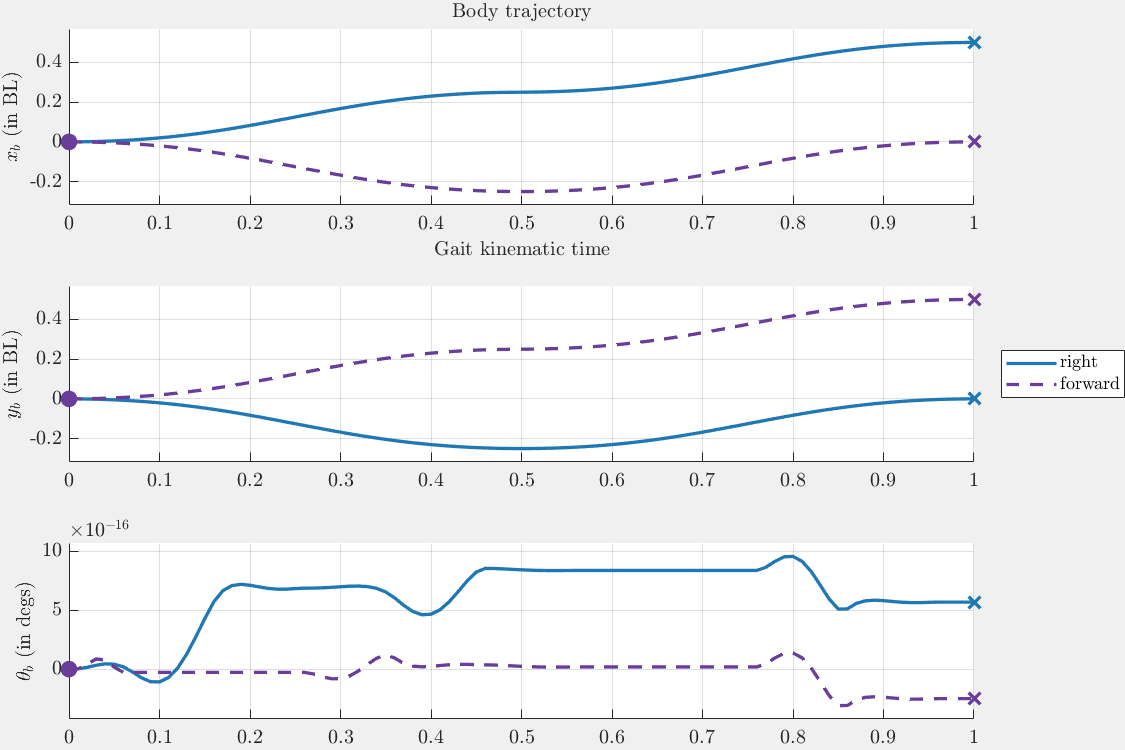

% couple the full local connection into cell array to compute the body
% trajectory
fA = {  fAfull_i{ sIdx(1) }; fAfull_i{ sIdx(2) }  };

% compute the nominal length of the body for the chosen parameters
BL = nominalBodyLength(nl, bodySprawlParam(end));

% package the parameters for the simulation
% ... gait parameters will be the same for both gait cycles
params = [];
params.dnum = dnum;
params.na = na; params.nl = nl; 
params.nalpha_b = nalpha_b( bsIdx );  % choose the omnidirectional configuration
params.sHat = sHat;

% compute the trajectory of the system for each cycle
[~, ybRht, ~] = simulateSineSwingGaits(fA, params, sPhase_Rht);
[~, ybFwd, ~] = simulateSineSwingGaits(fA, params, sPhase_Fwd);

% plot the trajectory for the system as a function of the kinematic phase
% (timeseries-like)
plotBodyTrajectoryTimeseries( BL, {ybRht, ybFwd}, {'right', 'forward'} );

Finally, we add the rotary gait in as well to obtain the full picture for simple gait design for the CLARI system in its nominal omnidirectional configuration. A quick sketch of the rotary gait design is provided below.

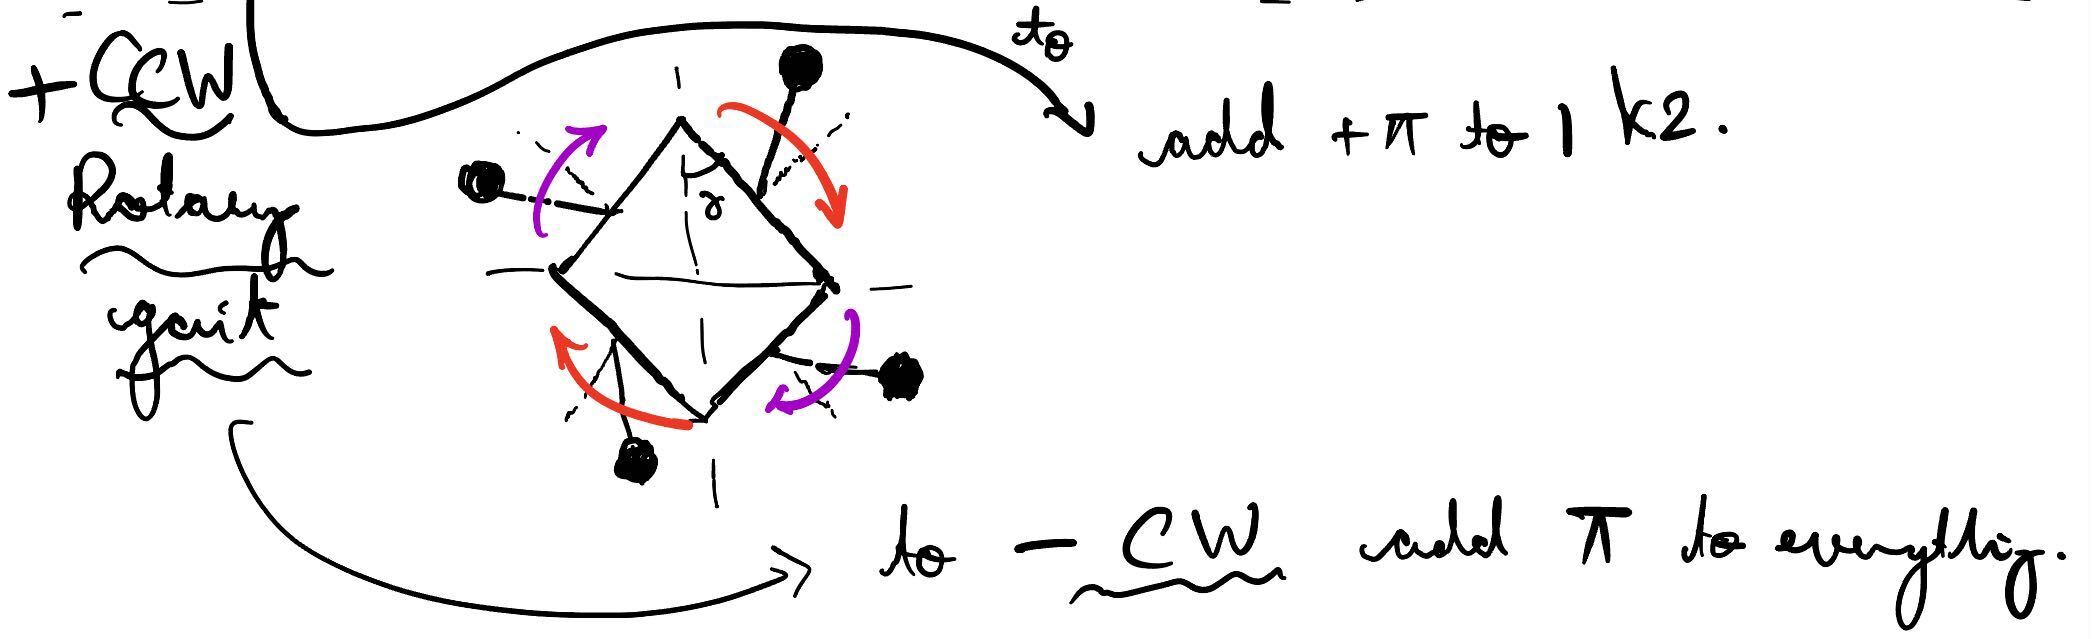

We obtain this gait by perturbing the phases of a right-displacing gait (make the fore limbs $180^{\circ}$ off) and them obtain the body trajectory and plot everything together as we did above.

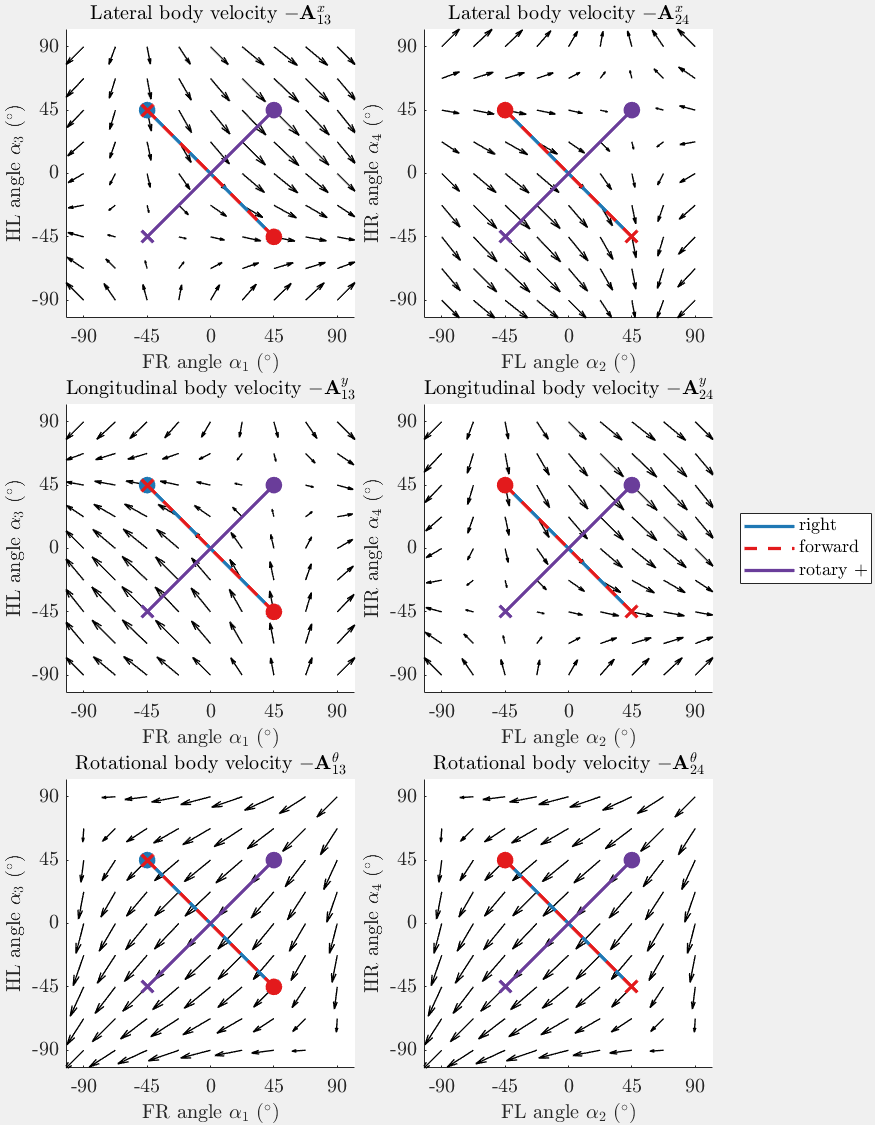

% rotary gait construction
sPhase_Rot = [pi, pi, 0, 0]'; % we switch the motion of the hind limbs to obtain a rotary gait
[phiRot, ~] = computeSineShapeTrajectoriesV1(t, sHat, sPhase_Rot);
phiRotWt = [t(:)'; phiRot];

% rotary gait body trajectory
[~, ybRot, ~] = simulateSineSwingGaits(fA, params, sPhase_Rot);

% plot the local connection and body trajectory (in kinematic phase) with all the gaits
plotTrotLocalConnWGaits( bsIdx, {phiRhtWt, phiFwdWt, phiRotWt}, {'right', 'forward', 'rotary +'}, true );

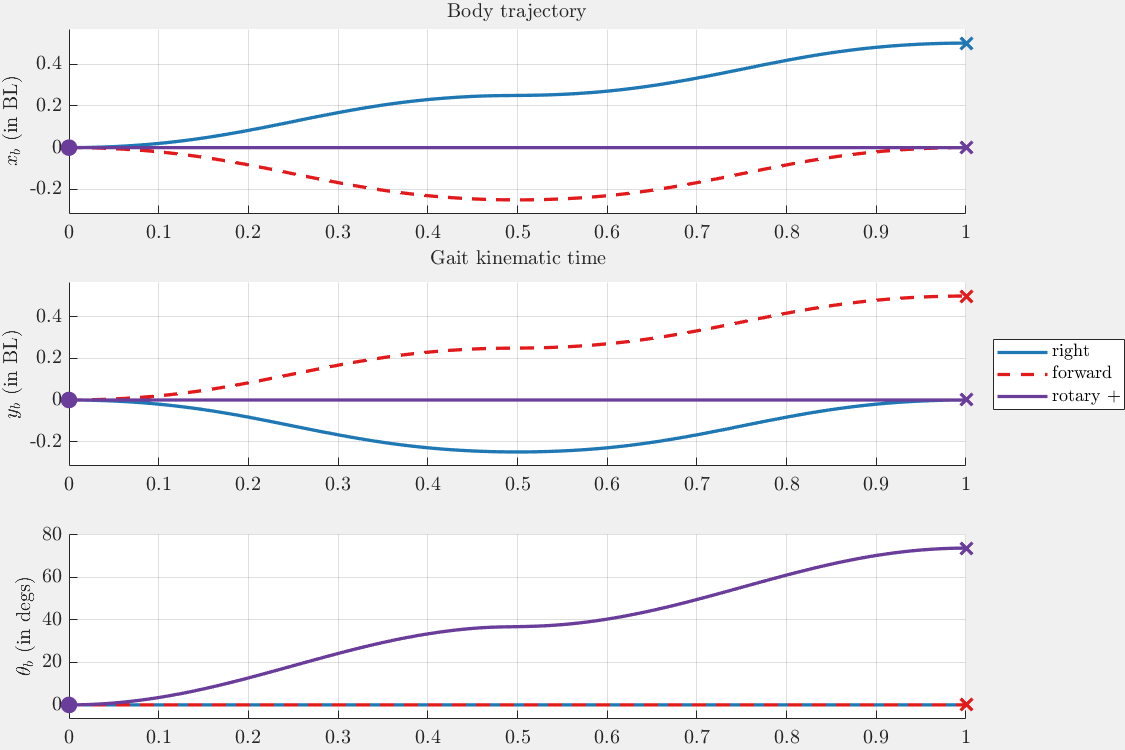

plotBodyTrajectoryTimeseries( BL, {ybRht, ybFwd, ybRot}, {'right', 'forward', 'rotary +'} );

Finally, we plot the gait trajectories with snapshots in the position space.

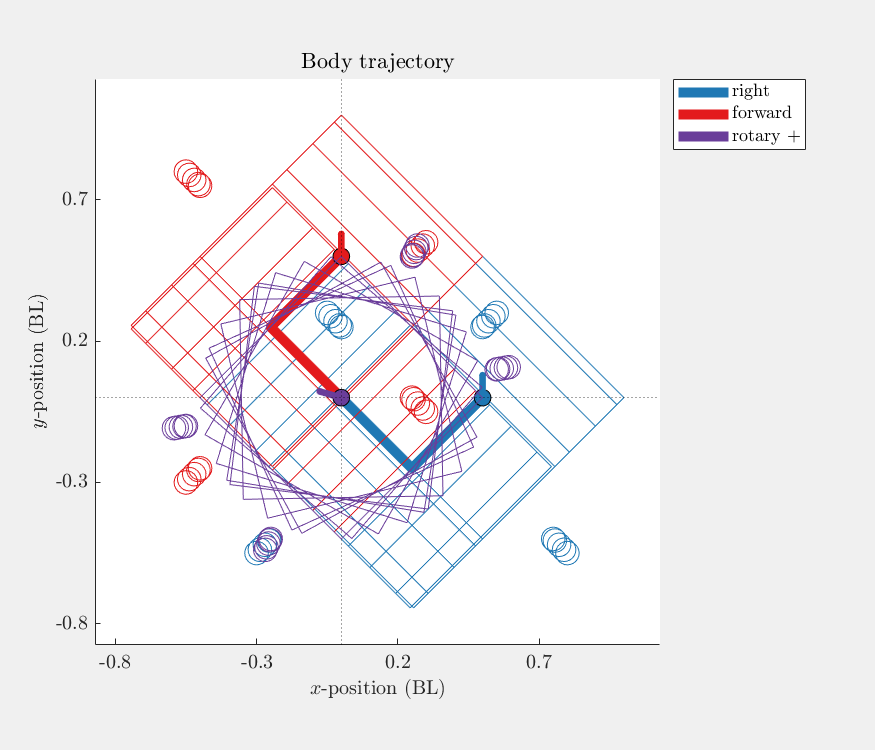

% load the params for computing body trajectory snapshots
clear params;
params.na = na; params.nl = nl; params.nalpha_b = nalpha_b( bsIdx );

% pack the body and foot transforms
transforms.fh_e__boxCorners = fh_e__boxCorners;
transforms.fz_boxCorners = fz_boxCorners;
transforms.fh_e__i = fh_e__i;

% load the different gait configuration trajectories
gaitConfigTrajsIn = ...
    {  [ t(:), ybRht, phiRht' ], ...
       [ t(:), ybFwd, phiFwd' ], ...
       [ t(:), ybRot, phiRot' ]    };

% choose percentage of the points to plot
prctpts = 10; % ENTER PERCENTAGE 
fracPts = prctpts/100;

% compute the body trajectory snapshots
[timeTrajs, bodyTrajs, stanceBodyTrajs] = computeBodyTrajSnapshots...
    (params, transforms, gaitConfigTrajsIn, fracPts);

% additionally provide the stance array for the feet
stanceFeetOrder = nan(1, 4);
stanceFeetOrder(  cs(sIdx(1), :)  ) = 1;
stanceFeetOrder(  cs(sIdx(2), :)  ) = 2;

% plot the snapshots of the gait cycles
plotBodyTrajSnapshots( ...
    BL, ...
    timeTrajs, {t(:), ybRht, ybFwd, ybRot}, ...
    bodyTrajs, ...
    stanceFeetOrder, stanceBodyTrajs, ...
    {'right', 'forward', 'rotary +'} ...
                        );

We also plot these trajectories individually to obtain a sense for the motion in each stance phase.

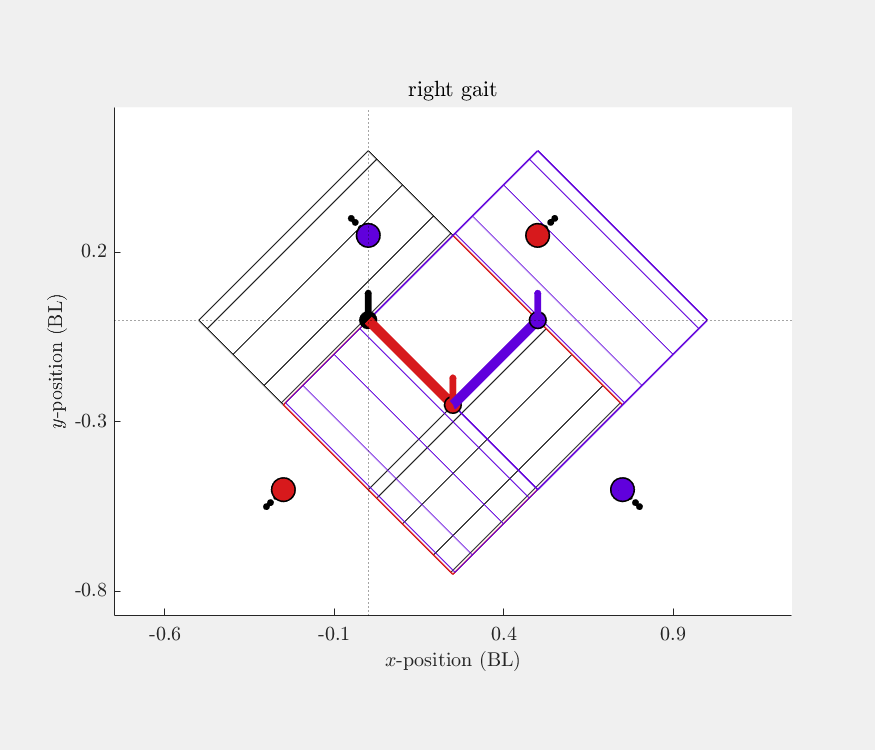

% load the configuration trajectories individually
rhtGaitConfigTrajIn = { [ t(:), ybRht, phiRht' ] };
fwdGaitConfigTrajIn = { [ t(:), ybFwd, phiFwd' ] };
rotGaitConfigTrajIn = { [ t(:), ybRot, phiRot' ] };

% compute it individually and plot
[timeTrajs, bodyTrajs, stanceBodyTrajs] = computeBodyTrajSnapshots...
    (params, transforms, rhtGaitConfigTrajIn, fracPts);
plotBodyTrajSnapshots( ...
    BL, ...
    timeTrajs, {t(:), ybRht}, ...
    bodyTrajs, ...
    stanceFeetOrder, stanceBodyTrajs, ...
    {'right'} ...
                        );

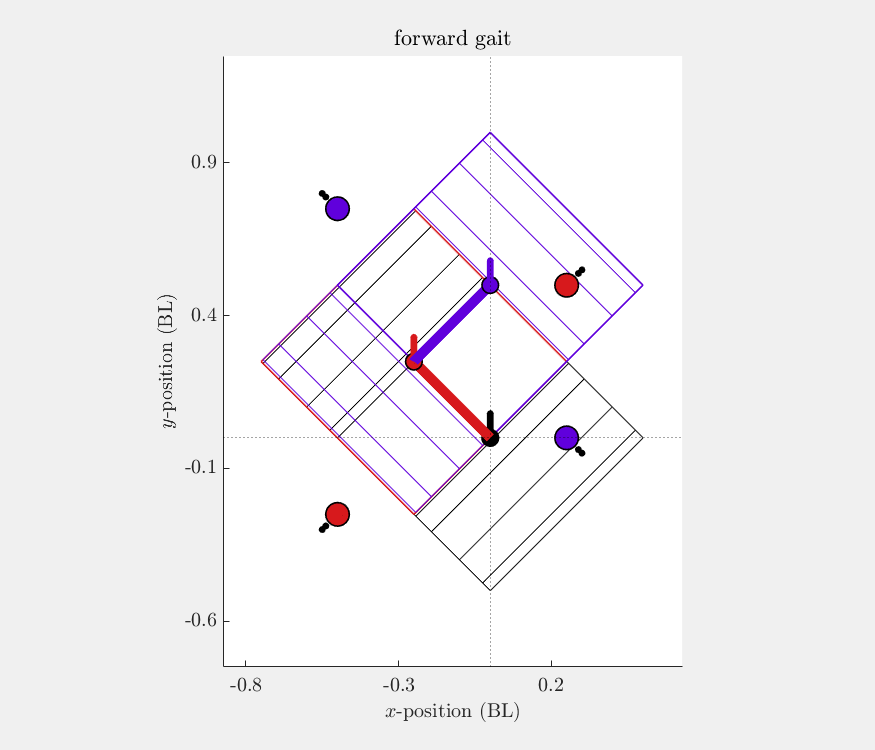

[timeTrajs, bodyTrajs, stanceBodyTrajs] = computeBodyTrajSnapshots...
    (params, transforms, fwdGaitConfigTrajIn, fracPts);
plotBodyTrajSnapshots( ...
    BL, ...
    timeTrajs, {t(:), ybFwd}, ...
    bodyTrajs, ...
    stanceFeetOrder, stanceBodyTrajs, ...
    {'forward'} ...
                        );

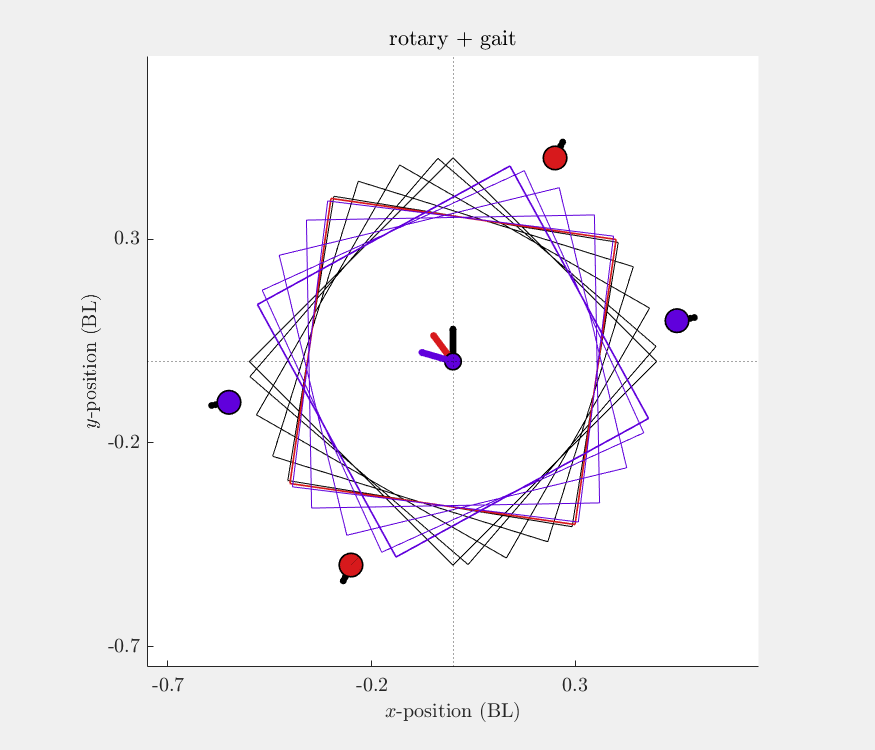

[timeTrajs, bodyTrajs, stanceBodyTrajs] = computeBodyTrajSnapshots...
    (params, transforms, rotGaitConfigTrajIn, fracPts);
plotBodyTrajSnapshots( ...
    BL, ...
    timeTrajs, {t(:), ybRot}, ...
    bodyTrajs, ...
    stanceFeetOrder, stanceBodyTrajs, ...
    {'rotary +'} ...
                        );

addpath(genpath('Data')); addpath(genpath('Utility Functions'));
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
load('Data\nonslip4CLARIMobility.mat');
% ... specifically helps us not reload unnecessary parameters
load('Data\Sinusoidal Gaits\clariConnVecF.mat');
% ... 
set(groot, 'defaultAxesTickLabelInterpreter', 'latex'); 
set(groot, 'defaulttextinterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
sympref('AbbreviateOutput', false); % need full expressions for the next section

Before we explore more global properties of the system, the first step is to show that the system is gait controllable. For this, we assume the system operates around the origin of the shape space (the nominal position of the limb angles) and further only consider the actuation of FR and FL limbs. Although we only consider these two set of limbs, the analysis below also extends to other pairs distributed across the two different contact submanifolds - $S_{13}$ and $S_{24}$.

However the first step is to obtain a function that helps us compute the vector field sweeps that we need.

% ... we perform the analysis on the omnidirectional configuration of the
% ... CLARI system
bsIdx = ceil( sNum/2 );

% ... compute the nominal length of the body for the chosen parameters
BL = nominalBodyLength(nl, bodySprawlParam(end));
% ... ... this will be used to normalize the body velocity representations

% ... choose your actuation directions from the available limb angles, and
% ... make sure they are spread out across S13 and S24
uI = 1; uII = 2;  % CHANGE HERE!
nu_nIorII = 1:4; % extract directions that are not actuated
nu_nIorII = nu_nIorII( nu_nIorII ~= uI & nu_nIorII ~= uII );

% ... find whether the actuated directions are the first or the second
% ... arguments in their corresponding local connection functions
argPosI  = find( cs( sIdx(1), : ) == uI  );
argPosII = find( cs( sIdx(2), : ) == uII );

% ... for the unactuated directions, we set their default values to zero or
% ... the origin of their shape subspace
nalpha_nIorII = zeros(1, 2);
% ... ... if you want to test the gait ctrb elsewhere, set it above and
% ... ... for ordering of the unactuated directions

% ... extract the functions to compute the vector fields both plainly and
% ... in the normalized version
fA_I = fA_i_col1{ sIdx(1) }; fA_II = fA_i_col2{ sIdx(2) };
fnA_I = fnA_i_col1{ sIdx(1) }; fnA_II = fnA_i_col2{ sIdx(2) };

% ... setup the sweep conditions and parameters
% ... ... nalpha_x: sweep in limb angles for the 1st dirn in S13
% ... ... nalpha_y: sweep in limb angles for the 2nd dirn in S24
nalphaVec = linspace(limbAngleParam(1), limbAngleParam(2), dnum);
[nalpha_x, nalpha_y] = meshgrid(nalphaVec, nalphaVec);

% ... let's extract a small subportion for plotting
iQ = round( linspace(1, dnum, dNumQ) );

% ... the 2D meshgrid is already in 'nalpha_x' and 'nalpha_y' for each
% ... contact vector field
% ... ensure that the unactuated directions are set uniformly to their
% ... default value
A_I = cell(3, 1);
switch argPosI % compute the vector field
    case 1
        A_I_sweep = fA_I( na, nl, nalpha_b(bsIdx), ...
                        nalpha_x(:)', ...
                        nalpha_nIorII(1)*ones(1, dnum^2)...
                        );
        nA_I_sweep = fnA_I( na, nl, nalpha_b(bsIdx), ...
                          nalpha_x(:)', ...
                          nalpha_nIorII(1)*ones(1, dnum^2)...
                          );
    case 2
        A_I_sweep = fA_I( na, nl, nalpha_b(bsIdx), ...
                        nalpha_nIorII(1)*ones(1, dnum^2), ...
                        nalpha_x(:)' ...
                        );
        nA_I_sweep = fnA_I( na, nl, nalpha_b(bsIdx), ...
                          nalpha_nIorII(1)*ones(1, dnum^2), ...
                          nalpha_x(:)' ...
                          );
end % save it in cells
A_I{1} = reshape( A_I_sweep(1, :), [dnum, dnum] );
A_I{2} = reshape( A_I_sweep(2, :), [dnum, dnum] );
A_I{3} = reshape( A_I_sweep(3, :), [dnum, dnum] );
nA_I   = nA_I_sweep;
% ... ... repeat the process for the other direction
A_II = cell(3, 1);
switch argPosII
    case 1
        A_II_sweep = fA_II( na, nl, nalpha_b(bsIdx), ...
                         nalpha_y(:)', ...
                         nalpha_nIorII(1)*ones(1, dnum^2)...
                         );
        nA_II_sweep = fnA_II( na, nl, nalpha_b(bsIdx), ...
                           nalpha_y(:)', ...
                           nalpha_nIorII(1)*ones(1, dnum^2)...
                           );
    case 2
        A_II_sweep = fA_II( na, nl, nalpha_b(bsIdx), ...
                         nalpha_nIorII(1)*ones(1, dnum^2), ...
                         nalpha_y(:)' ...
                         );
        nA_II_sweep = fnA_II( na, nl, nalpha_b(bsIdx), ...
                           nalpha_nIorII(1)*ones(1, dnum^2), ...
                           nalpha_y(:)' ...
                           );
end
A_II{1} = reshape( A_II_sweep(1, :), [dnum, dnum] );
A_II{2} = reshape( A_II_sweep(2, :), [dnum, dnum] );
A_II{3} = reshape( A_II_sweep(3, :), [dnum, dnum] );
nA_II   = nA_II_sweep;

% ... next, we compute the dot product of these two vectors to ascertain 
% ... how independent they are
nA_I_dot_nA_II = reshape( ...
                            sum( nA_I.*nA_II,  1 ), ...
                            [dnum, dnum] ...
                        );

This specific matrix is in the range of [-1,1] where the maxima and minima occur at a single point - so at all the other points, the vector fields for the chosen limbs are independent. We should this using contours at 0.99 and -0.99 respectively instead of exactly solving for the maxima and minima.

% ... finally, we also compute the lie bracket between the two vector
% ... fields - the theta component is always zero because rotations are
% ... commutative in planar locomotion problems
% ... ... compute the limits of the lie-bracket for contour plots
lieBrkt_nA_I_II = cell(1, 2);
lieBrkt_nA_I_II_sweep = ...
    computeLieBracketOfse2VectorFields...
        ( A_I_sweep, A_II_sweep );
lieBrkt_nA_I_II{1} = reshape( lieBrkt_nA_I_II_sweep(1, :), ...
                                [dnum, dnum] );
lieBrkt_nA_I_II{2} = reshape( lieBrkt_nA_I_II_sweep(2, :), ...
                                [dnum, dnum] );
lieBrktLim = max( abs(lieBrkt_nA_I_II_sweep), [], "all" )*[-1, 1];

Now, we have all the quantities to plot - plot first the vector field, then their span through the dot product (scalar field), and then lie-bracket to show that the system is gait controllable.

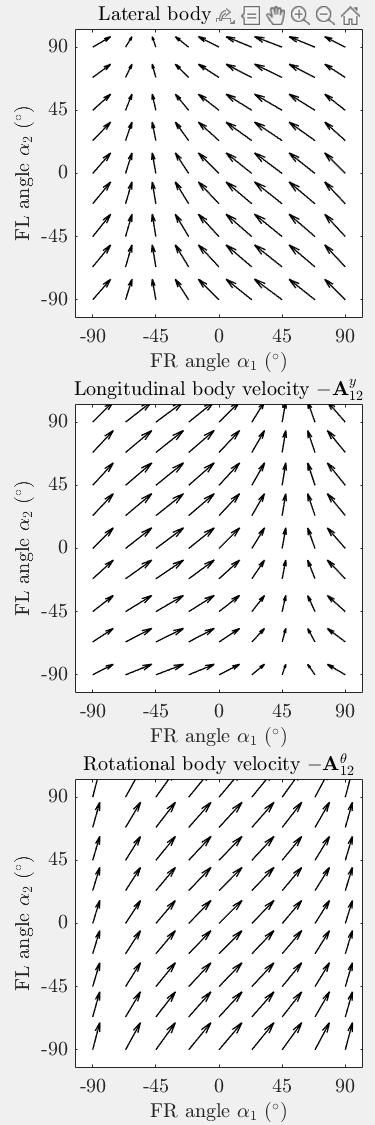

% string to represent actuated direction, local connection, spans, etc.
limbStr = {'FR', 'FL', 'HL', 'HR'};
aStr = { ' angle $\alpha_{', '}$ $({}^{\circ})$' };
uIstr = num2str(uI); uIIstr = num2str(uII);
aIstr  = [limbStr{uI},  aStr{1}, uIstr,  aStr{2}];
aIIstr = [limbStr{uII}, aStr{1}, uIIstr, aStr{2}];
shapeDirnStr = num2str([uI, uII], '%d%d');
Astr = '\mathbf{A}';
unitVecAstr = ['\hat{' Astr '}']; % '-' not required for dot product

% plot the local connection vector field generated by the actuated limb
% angles
plot2DLocalConnWOGaits( ...
    {nalpha_x, nalpha_y}, ... % x and y values for the vector field
    {angleLimits, angleLimits}, ... % x, y limits and ticks
    {angleTicks, angleTicks}, ...
    BL, ...
    A_I, A_II, ... % connection vector fields
    {aIstr, aIIstr}, ... % label and title strings
    { ... 
     ['Lateral body velocity $-\mathbf{A}^{x}_{' shapeDirnStr '}$'], ...
     ['Longitudinal body velocity $-\mathbf{A}^{y}_{' shapeDirnStr '}$'], ...
     ['Rotational body velocity $-\mathbf{A}^{\theta}_{' shapeDirnStr '}$'] ...
    }, iQ ... % plot a subportion of the vector field
                        );

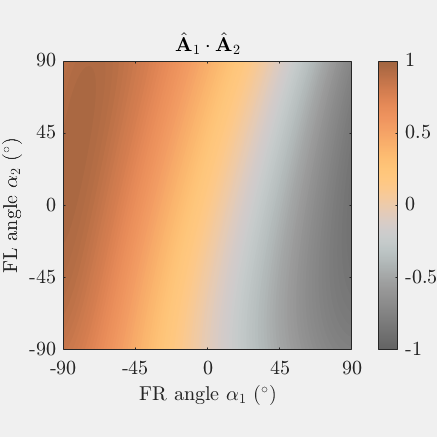

% we need sharper bounds for contour maps unlike the vector field, so we
% obtain angle limits accordingly
angleLimStrict = rad2deg( ...
    [limbAngleParam(1), limbAngleParam(2)] ...
    );

% next we explore the span of this vector field by plotting the normalized
% dot product of the two directions
plot2DnormDotOfLocalConnWOGaits( ...
    {nalpha_x, nalpha_y}, ...
    {angleLimStrict, angleLimStrict}, ...
    {angleTicks, angleTicks}, ...
    nA_I_dot_nA_II, ...
    {aIstr, aIIstr}, ...
    ['$' unitVecAstr '_{' uIstr '} \cdot' ...
         unitVecAstr '_{' uIIstr '}$'] ...
                                );

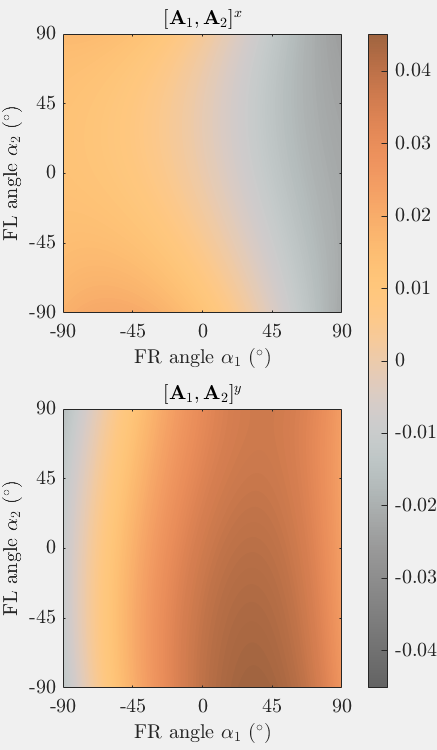

% lastly, we plot the lie-bracket for visualization purposes
plotLiebrktOf2DLocalConnWOGaits( ...
    {nalpha_x, nalpha_y}, ...
    {angleLimStrict, angleLimStrict}, ...
    {angleTicks, angleTicks}, ...
    lieBrktLim, ...
    BL, ...
    lieBrkt_nA_I_II, ...
    {aIstr, aIIstr}, ...
    ['[' Astr '_{' uIstr '}, ' Astr '_{' uIIstr '}]'] ...
                                );

We have shown that the system is gait controllable in a simple way. The final Lie-bracket plot is made just for visualization purposes.

load('Data\lvl2CSinfo.mat'); load('Data\nonslip4CLARIMobility.mat');

sympref('AbbreviateOutput', false);

Finally, we move on to exploring more global 

Consider the more general case of sinusoidal subgaits of the form:


$$\alpha_i = a_i \cos{\left( 2 \pi \tau + P_i \right)} + b_i \\ \alpha_j = a_j \cos{\left( 2 \pi \tau + P_j \right)} + b_j \\$$


where the gait parameters are the amplitudes, biases, and phases in the contact submanifold $S_{ij}$. This makes a total of 6 parameters per stance phase and in a two-stance gait like trot, this results in a 12-dimensional gait space which can not be explored exhaustively.

So, we seek a few different ways to simplify the reachable set generation process, and the first of which is going to be symbolic reduction assuming the inputs are of the following form.

% some params
sIdx = cs_IdxFor2bGaits(strcmp(csString, 'Trot'), :);
na = limbScalingParam(end); nl = 1;
nalpha_b = bodySprawlParam(end);
nalpha0 = limbAngleParam(end);
swingHat = pi/4;
nominalBodyLength = matlabFunction( ...
            simplify(norm(boxCornersFromBody(2, 1:2) - boxCornersFromBody(4, 1:2))), ...
            "Vars", [l, alpha_b] ...
                                    );
BL = nominalBodyLength(nl, nalpha_b);

Initially, we assume the CLARI system is in its omnidirection configuration, $\alpha_{b} = \frac{\pi}{4}$, and see if we can simplify the local connection.

A13 = simplify(subs( A_i{sIdx(1)}, [a, l, alpha_b], [na, nl, nalpha_b] ))

Now, we define the limb angles symbolically:

% init symbolic gait parameters
syms A_1 A_3 real positive % variables for amplitudes
syms B_1 B_3 P_1 P_3 real % for biases and relative phase
syms tau real; assume(tau >= 0 & tau <= 1); % kinematic gait time (between 0 and 1)

% define the sinusoidal limb fore-aft angles
alpha_1_cos = A_1 * cos(2*pi*tau + P_1) + B_1

$$alpha\_1\_cos = B_{1}+A_{1}\,\cos\left(P_{1}+2\,\pi \,\tau \right)$$

alpha_3_cos = A_3 * cos(2*pi*tau + P_3) + B_3

$$alpha\_3\_cos = B_{3}+A_{3}\,\cos\left(P_{3}+2\,\pi \,\tau \right)$$

% obtain their velocities symbolically
alphaDot_1_cos = simplify( diff(alpha_1_cos, tau) )

$$alphaDot\_1\_cos = -2\,\pi \,A_{1}\,\sin\left(P_{1}+2\,\pi \,\tau \right)$$

alphaDot_3_cos = simplify( diff(alpha_3_cos, tau) )

$$alphaDot\_3\_cos = -2\,\pi \,A_{3}\,\sin\left(P_{3}+2\,\pi \,\tau \right)$$

% substitute in the local connection above and try to simplify
subs(A13, [alpha_1, alpha_3], [alpha_1_cos, alpha_3_cos])

% obtain the body velocity now as a function of the sinusoidal limb
% trajectories
simplify( subs(A13, ...
              [alpha_1, alpha_3], ...
              [alpha_1_cos, alpha_3_cos])* ...
                [alphaDot_1_cos; alphaDot_3_cos] )

Turns out we can incorporate the gait parameters into the local connection (or the motility map in this case which directly provides the body velocity). Let's make this more general by incorporating the robot construction parameters, $a$ and $l$, back in along with a general sprawl angle, $\alpha_b$.

gCirc13p = simplify( subs(-A_i{sIdx(1)}, ...
              [alpha_1, alpha_3], ...
              [alpha_1_cos, alpha_3_cos])* ...
                [alphaDot_1_cos; alphaDot_3_cos] )

Let's repeat this procedure for the other stance phase:

syms A_2 A_4 real positive
syms B_2 B_4 P_2 P_4 real
alpha_2_cos = A_2 * cos(2*pi*tau + P_2) + B_2

$$alpha\_2\_cos = B_{2}+A_{2}\,\cos\left(P_{2}+2\,\pi \,\tau \right)$$

alpha_4_cos = A_4 * cos(2*pi*tau + P_4) + B_4

$$alpha\_4\_cos = B_{4}+A_{4}\,\cos\left(P_{4}+2\,\pi \,\tau \right)$$

alphaDot_2_cos = simplify( diff(alpha_2_cos, tau) )

$$alphaDot\_2\_cos = -2\,\pi \,A_{2}\,\sin\left(P_{2}+2\,\pi \,\tau \right)$$

alphaDot_4_cos = simplify( diff(alpha_4_cos, tau) )

$$alphaDot\_4\_cos = -2\,\pi \,A_{4}\,\sin\left(P_{4}+2\,\pi \,\tau \right)$$

gCirc24p = simplify( subs(-A_i{sIdx(2)}, ...
              [alpha_2, alpha_4], ...
              [alpha_2_cos, alpha_4_cos])* ...
                [alphaDot_2_cos; alphaDot_4_cos] )

Let's do this properly while negating the local connection to obtain the motility map and store this in memory.

% init and store the body velocity functions for later computations
fgCirc = cell(1, 2);
fgCirc{1} = matlabFunction( ...
    gCirc13p, "Vars", [tau, a, l, alpha_b, A_1, A_3, P_1, P_3, B_1, B_3] ...
                            );
fgCirc{2} = matlabFunction( ...
    gCirc24p, "Vars", [tau, a, l, alpha_b, A_2, A_4, P_2, P_4, B_2, B_4] ...
                            );

% convert the limb angle symbolic variables into functions
falpha_cos = cell(1, 4); falphaDot_cos = cell(1, 4);
falpha_cos{1} = matlabFunction( ...
    alpha_1_cos, "Vars", [tau, A_1, P_1, B_1] );
falpha_cos{2} = matlabFunction( ...
    alpha_2_cos, "Vars", [tau, A_2, P_2, B_2] );
falpha_cos{3} = matlabFunction( ...
    alpha_3_cos, "Vars", [tau, A_3, P_3, B_3] );
falpha_cos{4} = matlabFunction( ...
    alpha_4_cos, "Vars", [tau, A_4, P_4, B_4] );
falphaDot_cos{1} = matlabFunction( ...
    alphaDot_1_cos, "Vars", [tau, A_1, P_1, B_1] );
falphaDot_cos{2} = matlabFunction( ...
    alphaDot_2_cos, "Vars", [tau, A_2, P_2, B_2] );
falphaDot_cos{3} = matlabFunction( ...
    alphaDot_3_cos, "Vars", [tau, A_3, P_3, B_3] );
falphaDot_cos{4} = matlabFunction( ...
    alphaDot_4_cos, "Vars", [tau, A_4, P_4, B_4] );

% store the functions for the limb angles, limb angular velocities, and
% body velocities
save('Data\Sinusoidal Gaits\gCircFxns.mat', ...
    'A_1', 'A_2', 'A_3', 'A_4', ...
    'P_1', 'P_2', 'P_3', 'P_4', ...
    'B_1', 'B_2', 'B_3', 'B_4', ...
    'falpha_cos', 'falphaDot_cos', ...
    'gCirc13p', 'gCirc24p', 'fgCirc');

addpath(genpath('Data')); addpath(genpath('Utility Functions'));
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
load('Data\nonslip4CLARIMobility.mat'); load('Data\Sinusoidal Gaits\clariConnVecF.mat');

load('Data\Sinusoidal Gaits\gCircFxns.mat');
set(groot, 'defaultAxesTickLabelInterpreter', 'latex'); 
set(groot, 'defaulttextinterpreter', 'latex');
set(groot, 'defaultLegendInterpreter', 'latex');
sympref('AbbreviateOutput', false);

In this section, we finally explore global locomotive properties of the CLARI system in the sprawl-locked configuration.

% choose the omnidirectional configuration of the CLARI system
bsIdx = ceil( sNum/2 );

% set the discretization per dimension
% ... based on prior sweeps, the discretization should be in the 
% ... set {3, 5, 7} - 7 at the most
uDisc = 7;

% generate the input space when provide with limits for the shape
% ... trajectories, limb angle parameters, and input space discretization
% ... the max amplitude is not set to 45degs
stanceSpace = generateInputForSineSubgaits( limbAngleParam, limbAngleParam(2)/2, uDisc );
% ... pad the "stanceInputs" with contact states for each stance phase
stanceSpace.cs = cs(sIdx, :);

% setup the params for simulation
params = [];
params.na = na; params.nl = nl; params.nalpha_b = nalpha_b( bsIdx );

% simulate the stance phase trajectories of the system
% ... treat both subgaits using the same input space and generate
% ... trajectories in each subspace, we obtain their respective subgait
% ... average velocities, then take their convex hulls, and perform a
% ... Minkowski addition in the Lie-algebra to obtain a commutative
% ... overapproximation
tic; stanceSpace = simulateSineSubgaits( params, stanceSpace ); toc;

Elapsed time is 27.589271 seconds.


% compute the Minkowski addition(-ish) based estimate of the convex hull of the
% full trot gait cycle reachable set
% ... note: this is a commutative approximation of the full-cycle 
% ...       reachable set, and might need further improvements
tic; appxGaitSpace = convexCommuttReachSetEst( stanceSpace ); toc;

Elapsed time is 0.435431 seconds.


The natural next step is to plot the stancewise displacement and gait-average velocities in each stance phase as 3D plots and 2D projection plots.

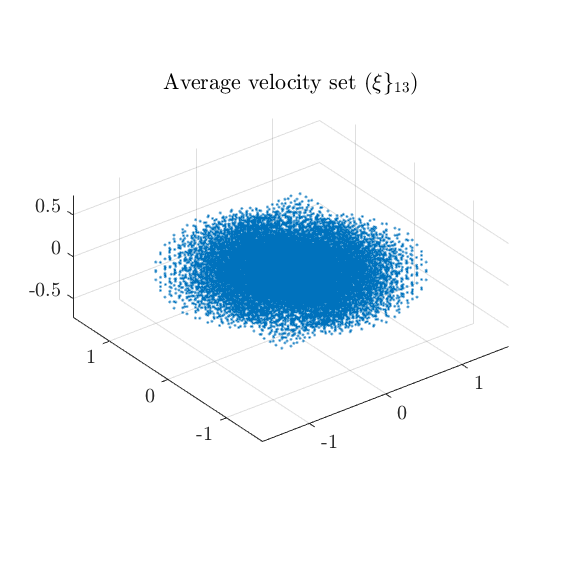

gCA = stanceSpace.gCA;
fS = 12; panelColor = 99/255*ones(1, 3);
figure('units', 'pixels', 'position', [0 0 450 450], ... % 
                'Color','w','Visible','on'); ax = gca;
scatter3(gCA{1}(:, 1), gCA{1}(:, 2), gCA{1}(:, 3), ...
    10, 'Marker', '.');
axis(ax, "equal", "padded"); ax.FontSize = fS; 

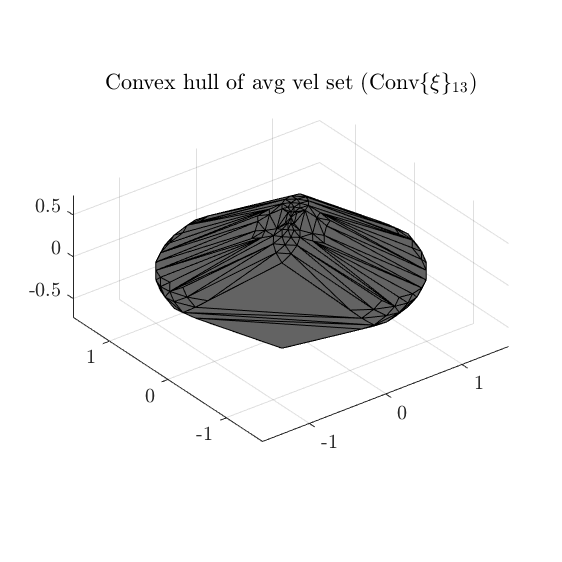

title(ax, 'Average velocity set ($\{\xi\}_{13}$)');
figure('units', 'pixels', 'position', [0 0 450 450], ...
                'Color','w','Visible','on'); ax = gca;
trisurf(stanceSpace.k{1}, ...
    gCA{1}(:, 1), gCA{1}(:, 2), gCA{1}(:, 3), ...
    'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelColor);
axis(ax, "equal", "padded"); ax.FontSize = fS; 

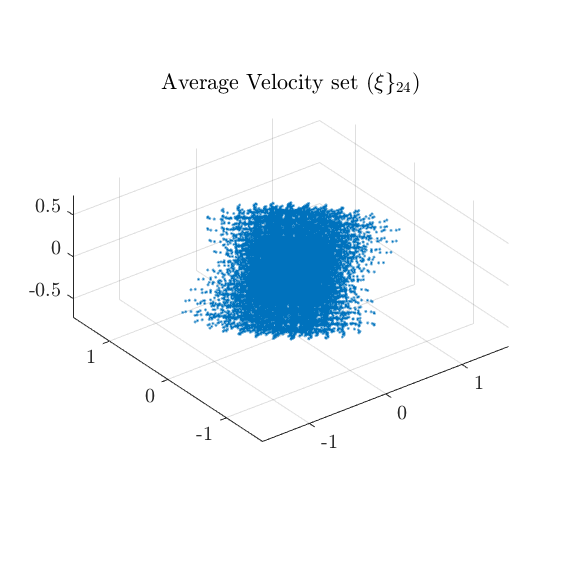

title(ax, ['Convex hull of avg vel set ' ...
    '($\mathrm{Conv}\{\xi\}_{13}$)']);
fS = 12; panelColor = 99/255*ones(1, 3);
figure('units', 'pixels', 'position', [0 0 450 450], ...
                'Color','w','Visible','on'); ax = gca;
scatter3(gCA{2}(:, 1), gCA{2}(:, 2), gCA{2}(:, 3), ...
    10, 'Marker', '.');
axis(ax, "equal", "padded"); ax.FontSize = fS; 

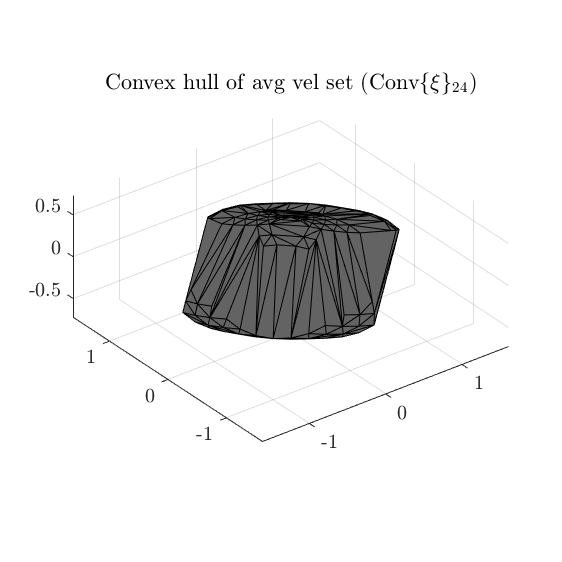

title(ax, 'Average Velocity set ($\{\xi\}_{24}$)');
figure('units', 'pixels', 'position', [0 0 450 450], ...
                'Color','w','Visible','on'); ax = gca;
trisurf(stanceSpace.k{1}, ...
    gCA{2}(:, 1), gCA{2}(:, 2), gCA{2}(:, 3), ...
    'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelColor);
axis(ax, "equal", "padded"); ax.FontSize = fS; 
title(ax, ['Convex hull of avg vel set ' ...

    '($\mathrm{Conv}\{\xi\}_{24}$)']);

Here, we plot the constructed reachable set for the complete cycle.

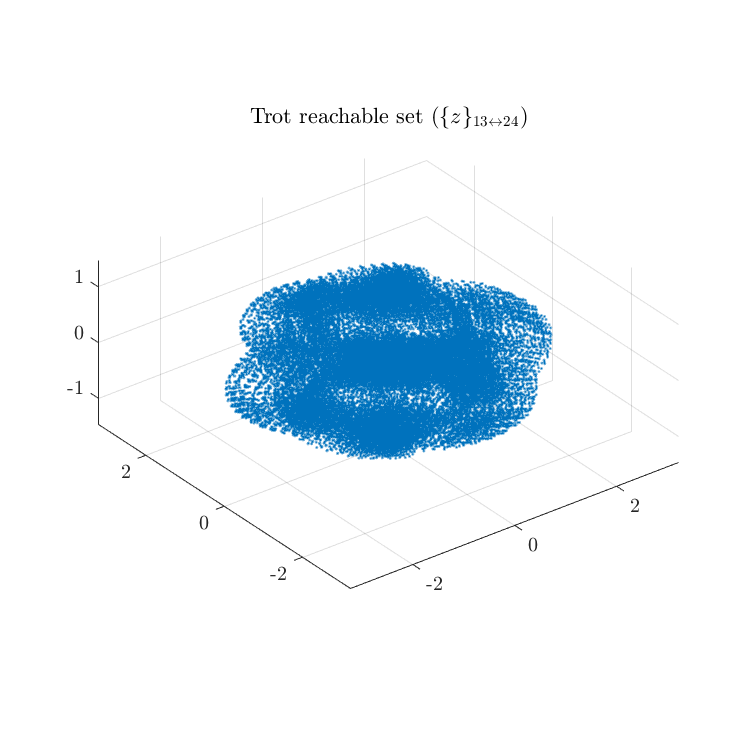

gCA = appxGaitSpace.gCA;
z = appxGaitSpace.z;

fS = 12; panelColor = 99/255*ones(1, 3);

figure('units', 'pixels', 'position', [0 0 600 600], ... 
                'Color','w','Visible','on'); ax = gca;
scatter3(z(:, 1), z(:, 2), z(:, 3), ...
    10, 'Marker', '.');
axis(ax, "equal", "padded"); ax.FontSize = fS; 
title(ax, ['Trot reachable set ' ...
    '($\{z\}_{13 \leftrightarrow 24}$)']);

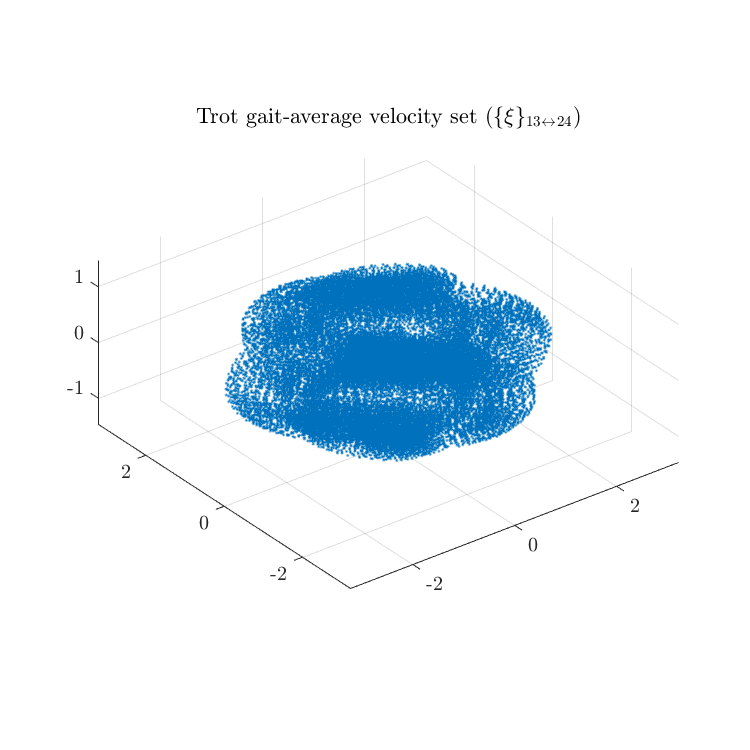


figure('units', 'pixels', 'position', [0 0 600 600], ... 
                'Color','w','Visible','on'); ax = gca;
scatter3(gCA(:, 1), gCA(:, 2), gCA(:, 3), ...
    10, 'Marker', '.');
axis(ax, "equal", "padded"); ax.FontSize = fS; 
title(ax, ['Trot gait-average velocity set ' ...
    '($\{\xi\}_{13 \leftrightarrow 24}$)']);